# **Práctica 1: Introducción a la Wavelet Toolbox de MATLAB**

## **Ejercicio 1. Generar señales. **

***Crear señales de longitud 2048 que representen cada función en el intervalo [0,1]. Representarlas gráficamente.***

% Generar el intervalo [0,1] de longitud 2048
x = linspace(0,1,2048);

**1) **$f(x)=1$

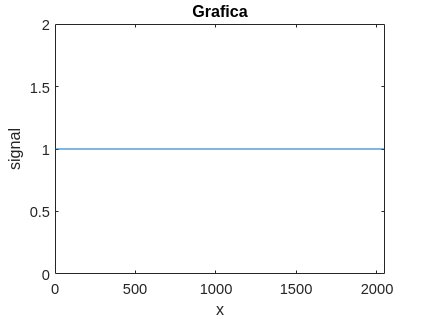

% Crear la señal 
fx1 = ones(size(x));

% Gráficar
plot(fx1)
title('Grafica')
xlabel('x')
ylabel('signal')
axis([0 length(fx1) min(fx1)-1 max(fx1)+1])

**2) **$f(x)=x^2(1-x)$

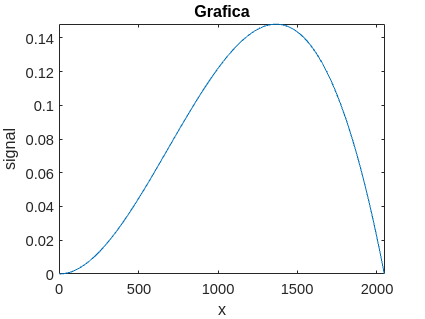

% Crear la señal 
fx2 = x.^2.*(1-x);

% Gráficar
plot(fx2)
title('Grafica')
xlabel('x')
ylabel('signal')
axis([0 length(fx2) min(fx2) max(fx2)])

**3) **$f(x)=x^4(1-x)^6\cos(64\pi x)$

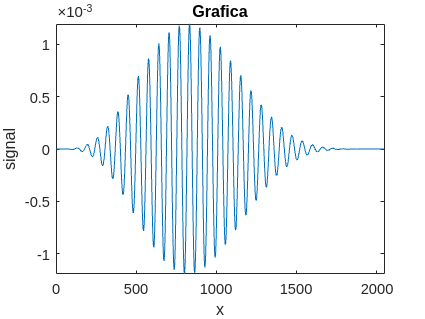

% Crear la señal 
fx3 = x.^4.*(1-x).^6.*cos(64*pi*x);

% Gráficar
plot(fx3)
title('Grafica')
xlabel('x')
ylabel('signal')
axis([0 length(fx3) min(fx3) max(fx3)])

**4) **$f (x) = 1(0,2 < x < 0,3) - 3(0,4 < x < 0,5) + 2(0,5 < x < 0,8)$

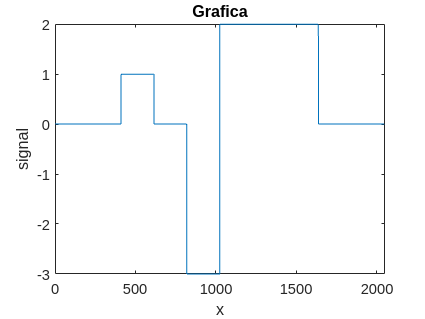

% Crear la señal
fx4 = zeros(size(x));
fx4((0.2 < x) & (x < 0.3)) = 1;
fx4((0.4 < x) & (x < 0.5)) = -3;
fx4((0.5 < x) & (x < 0.8)) = 2;

% Gráficar
plot(fx4)
title('Grafica')
xlabel('x')
ylabel('signal')
axis([0 length(fx4) min(fx4) max(fx4)])

**5) **$f (x) = sign(\sin(12\pi x))$

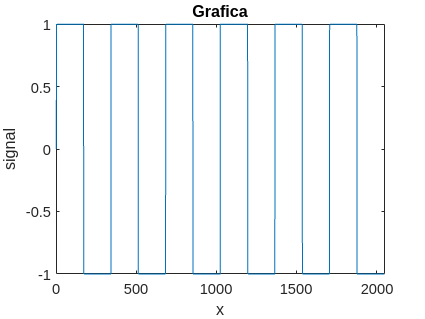

% Crear la señal 
fx5 = sign(sin(12*pi*x));

% Gráficar
plot(fx5)
title('Grafica')
xlabel('x')
ylabel('signal')
axis([0 length(fx5) min(fx5) max(fx5)])

## Ejercicio 2. Análisis Wavelet.

**Para cada una de las señales anteriores realizar las siguientes tareas utilizando diferentes wavelets y comparar los resultados.**

- ***Calcular la transformada wavelet de nivel 1. Obtener las subseñales tendencia y fluctuación. Representar gráficamente.***

**1) **$f(x)=1$

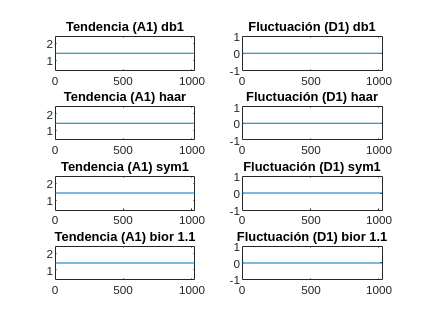

% Calculamos algunas transformadas wavelet

% Nivel 1
s = fx1;                                                % Señal
wdb1 = 'db1';                                           % Daubechies
whaar = 'haar';                                         % Haar
wsym1 = 'sym1';                                         % Symlets
wbior1_1 = 'bior1.1';                                   % Biorthogonal


% Transformadas
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                        % Daubechies
[Chaar,Lhaar] = wavedec(s,1,whaar);                     % Haar
[Csym1,Lsym1] = wavedec(s,1,wsym1);                     % Symlets
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);            % Biorthogonal


% Subseñales de tendencia y fluctiación (coeficientes)
cdb1_A1 = appcoef(Cdb1,Ldb1,wdb1,1);                    % Daubechies
cdb1_D1 = detcoef(Cdb1,Ldb1,1);                         % Daubechies

chaar_A1 = appcoef(Chaar,Lhaar,whaar,1);                % Haar
chaar_D1 = detcoef(Chaar,Lhaar,1);                      % Haar

csym1_A1 = appcoef(Csym1,Lsym1,wsym1,1);                % Symlets
csym1_D1 = detcoef(Csym1,Lsym1,1);                      % Symlets

cbior1_1_A1 = appcoef(Cbior1_1,Lbior1_1,wbior1_1,1);    % Biorthogonal
cbior1_1_D1 = detcoef(Cbior1_1,Lbior1_1,1);             % Biorthogonal


% Plots
figure; 
% Daubechies
subplot(4,2,1)
plot(cdb1_A1);title('Tendencia (A1) db1')
axis([0 length(cdb1_A1) min(cdb1_A1)-1 max(cdb1_A1)+1]);
subplot(4,2,2)
plot(cdb1_D1);title('Fluctuación (D1) db1')
axis([0 length(cdb1_D1) min(cdb1_D1)-1 max(cdb1_D1)+1]);

% Haar
subplot(4,2,3)
plot(chaar_A1);title('Tendencia (A1) haar')
axis([0 length(chaar_A1) min(chaar_A1)-1 max(chaar_A1)+1]);
subplot(4,2,4)
plot(chaar_D1);title('Fluctuación (D1) haar')
axis([0 length(chaar_D1) min(chaar_D1)-1 max(chaar_D1)+1]);

% Symlets
subplot(4,2,5)
plot(csym1_A1);title('Tendencia (A1) sym1')
axis([0 length(csym1_A1) min(csym1_A1)-1 max(csym1_A1)+1]);
subplot(4,2,6)
plot(csym1_D1);title('Fluctuación (D1) sym1')
axis([0 length(csym1_D1) min(csym1_D1)-1 max(csym1_D1)+1]);

% Biorthogonal
subplot(4,2,7)
plot(cbior1_1_A1);title('Tendencia (A1) bior 1.1')
axis([0 length(cbior1_1_A1) min(cbior1_1_A1)-1 max(cbior1_1_A1)+1]);
subplot(4,2,8)
plot(cbior1_1_D1);title('Fluctuación (D1) bior 1.1')
axis([0 length(cbior1_1_D1) min(cbior1_1_D1)-1 max(cbior1_1_D1)+1]);

**2) **$f(x)=x^2(1-x)$

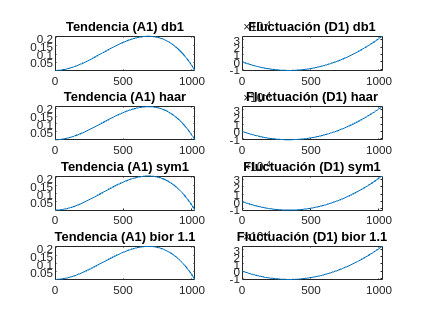

% Calculamos algunas transformadas wavelet

% Nivel 1
s = fx2;                                                % Señal
wdb1 = 'db1';                                           % Daubechies
whaar = 'haar';                                         % Haar
wsym1 = 'sym1';                                         % Symlets
wbior1_1 = 'bior1.1';                                   % Biorthogonal


% Transformadas
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                        % Daubechies
[Chaar,Lhaar] = wavedec(s,1,whaar);                     % Haar
[Csym1,Lsym1] = wavedec(s,1,wsym1);                     % Symlets
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);            % Biorthogonal


% Subseñales de tendencia y fluctiación (coeficientes)
cdb1_A1 = appcoef(Cdb1,Ldb1,wdb1,1);                    % Daubechies
cdb1_D1 = detcoef(Cdb1,Ldb1,1);                         % Daubechies

chaar_A1 = appcoef(Chaar,Lhaar,whaar,1);                % Haar
chaar_D1 = detcoef(Chaar,Lhaar,1);                      % Haar

csym1_A1 = appcoef(Csym1,Lsym1,wsym1,1);                % Symlets
csym1_D1 = detcoef(Csym1,Lsym1,1);                      % Symlets

cbior1_1_A1 = appcoef(Cbior1_1,Lbior1_1,wbior1_1,1);    % Biorthogonal
cbior1_1_D1 = detcoef(Cbior1_1,Lbior1_1,1);             % Biorthogonal


% Plots
figure; 
% Daubechies
subplot(4,2,1)
plot(cdb1_A1);title('Tendencia (A1) db1')
axis([0 length(cdb1_A1) min(cdb1_A1) max(cdb1_A1)]);
subplot(4,2,2)
plot(cdb1_D1);title('Fluctuación (D1) db1')
axis([0 length(cdb1_D1) min(cdb1_D1) max(cdb1_D1)]);

% Haar
subplot(4,2,3)
plot(chaar_A1);title('Tendencia (A1) haar')
axis([0 length(chaar_A1) min(chaar_A1) max(chaar_A1)]);
subplot(4,2,4)
plot(chaar_D1);title('Fluctuación (D1) haar')
axis([0 length(chaar_D1) min(chaar_D1) max(chaar_D1)]);

% Symlets
subplot(4,2,5)
plot(csym1_A1);title('Tendencia (A1) sym1')
axis([0 length(csym1_A1) min(csym1_A1) max(csym1_A1)]);
subplot(4,2,6)
plot(csym1_D1);title('Fluctuación (D1) sym1')
axis([0 length(csym1_D1) min(csym1_D1) max(csym1_D1)]);

% Biorthogonal
subplot(4,2,7)
plot(cbior1_1_A1);title('Tendencia (A1) bior 1.1')
axis([0 length(cbior1_1_A1) min(cbior1_1_A1) max(cbior1_1_A1)]);
subplot(4,2,8)
plot(cbior1_1_D1);title('Fluctuación (D1) bior 1.1')
axis([0 length(cbior1_1_D1) min(cbior1_1_D1) max(cbior1_1_D1)]);

**3) **$f(x)=x^4(1-x)^6\cos(64\pi x)$

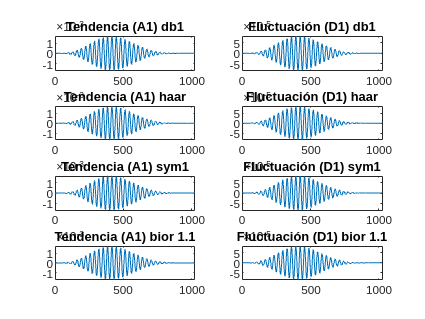

% Calculamos algunas transformadas wavelet

% Nivel 1
s = fx3;                                                % Señal
wdb1 = 'db1';                                           % Daubechies
whaar = 'haar';                                         % Haar
wsym1 = 'sym1';                                         % Symlets
wbior1_1 = 'bior1.1';                                   % Biorthogonal


% Transformadas
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                        % Daubechies
[Chaar,Lhaar] = wavedec(s,1,whaar);                     % Haar
[Csym1,Lsym1] = wavedec(s,1,wsym1);                     % Symlets
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);            % Biorthogonal


% Subseñales de tendencia y fluctiación (coeficientes)
cdb1_A1 = appcoef(Cdb1,Ldb1,wdb1,1);                    % Daubechies
cdb1_D1 = detcoef(Cdb1,Ldb1,1);                         % Daubechies

chaar_A1 = appcoef(Chaar,Lhaar,whaar,1);                % Haar
chaar_D1 = detcoef(Chaar,Lhaar,1);                      % Haar

csym1_A1 = appcoef(Csym1,Lsym1,wsym1,1);                % Symlets
csym1_D1 = detcoef(Csym1,Lsym1,1);                      % Symlets

cbior1_1_A1 = appcoef(Cbior1_1,Lbior1_1,wbior1_1,1);    % Biorthogonal
cbior1_1_D1 = detcoef(Cbior1_1,Lbior1_1,1);             % Biorthogonal


% Plots
figure; 
% Daubechies
subplot(4,2,1)
plot(cdb1_A1);title('Tendencia (A1) db1')
axis([0 length(cdb1_A1) min(cdb1_A1) max(cdb1_A1)]);
subplot(4,2,2)
plot(cdb1_D1);title('Fluctuación (D1) db1')
axis([0 length(cdb1_D1) min(cdb1_D1) max(cdb1_D1)]);

% Haar
subplot(4,2,3)
plot(chaar_A1);title('Tendencia (A1) haar')
axis([0 length(chaar_A1) min(chaar_A1) max(chaar_A1)]);
subplot(4,2,4)
plot(chaar_D1);title('Fluctuación (D1) haar')
axis([0 length(chaar_D1) min(chaar_D1) max(chaar_D1)]);

% Symlets
subplot(4,2,5)
plot(csym1_A1);title('Tendencia (A1) sym1')
axis([0 length(csym1_A1) min(csym1_A1) max(csym1_A1)]);
subplot(4,2,6)
plot(csym1_D1);title('Fluctuación (D1) sym1')
axis([0 length(csym1_D1) min(csym1_D1) max(csym1_D1)]);

% Biorthogonal
subplot(4,2,7)
plot(cbior1_1_A1);title('Tendencia (A1) bior 1.1')
axis([0 length(cbior1_1_A1) min(cbior1_1_A1) max(cbior1_1_A1)]);
subplot(4,2,8)
plot(cbior1_1_D1);title('Fluctuación (D1) bior 1.1')
axis([0 length(cbior1_1_D1) min(cbior1_1_D1) max(cbior1_1_D1)]);

**4) **$f (x) = 1(0,2 < x < 0,3) - 3(0,4 < x < 0,5) + 2(0,5 < x < 0,8)$

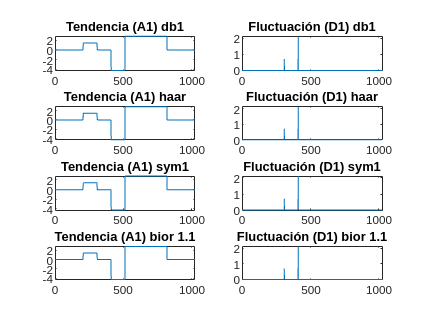

% Calculamos algunas transformadas wavelet

% Nivel 1
s = fx4;                                                % Señal
wdb1 = 'db1';                                           % Daubechies
whaar = 'haar';                                         % Haar
wsym1 = 'sym1';                                         % Symlets
wbior1_1 = 'bior1.1';                                   % Biorthogonal


% Transformadas
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                        % Daubechies
[Chaar,Lhaar] = wavedec(s,1,whaar);                     % Haar
[Csym1,Lsym1] = wavedec(s,1,wsym1);                     % Symlets
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);            % Biorthogonal


% Subseñales de tendencia y fluctiación (coeficientes)
cdb1_A1 = appcoef(Cdb1,Ldb1,wdb1,1);                    % Daubechies
cdb1_D1 = detcoef(Cdb1,Ldb1,1);                         % Daubechies

chaar_A1 = appcoef(Chaar,Lhaar,whaar,1);                % Haar
chaar_D1 = detcoef(Chaar,Lhaar,1);                      % Haar

csym1_A1 = appcoef(Csym1,Lsym1,wsym1,1);                % Symlets
csym1_D1 = detcoef(Csym1,Lsym1,1);                      % Symlets

cbior1_1_A1 = appcoef(Cbior1_1,Lbior1_1,wbior1_1,1);    % Biorthogonal
cbior1_1_D1 = detcoef(Cbior1_1,Lbior1_1,1);             % Biorthogonal


% Plots
figure; 
% Daubechies
subplot(4,2,1)
plot(cdb1_A1);title('Tendencia (A1) db1')
axis([0 length(cdb1_A1) min(cdb1_A1) max(cdb1_A1)]);
subplot(4,2,2)
plot(cdb1_D1);title('Fluctuación (D1) db1')
axis([0 length(cdb1_D1) min(cdb1_D1) max(cdb1_D1)]);

% Haar
subplot(4,2,3)
plot(chaar_A1);title('Tendencia (A1) haar')
axis([0 length(chaar_A1) min(chaar_A1) max(chaar_A1)]);
subplot(4,2,4)
plot(chaar_D1);title('Fluctuación (D1) haar')
axis([0 length(chaar_D1) min(chaar_D1) max(chaar_D1)]);

% Symlets
subplot(4,2,5)
plot(csym1_A1);title('Tendencia (A1) sym1')
axis([0 length(csym1_A1) min(csym1_A1) max(csym1_A1)]);
subplot(4,2,6)
plot(csym1_D1);title('Fluctuación (D1) sym1')
axis([0 length(csym1_D1) min(csym1_D1) max(csym1_D1)]);

% Biorthogonal
subplot(4,2,7)
plot(cbior1_1_A1);title('Tendencia (A1) bior 1.1')
axis([0 length(cbior1_1_A1) min(cbior1_1_A1) max(cbior1_1_A1)]);
subplot(4,2,8)
plot(cbior1_1_D1);title('Fluctuación (D1) bior 1.1')
axis([0 length(cbior1_1_D1) min(cbior1_1_D1) max(cbior1_1_D1)]);

**5) **$f (x) = sign(\sin(12\pi x))$

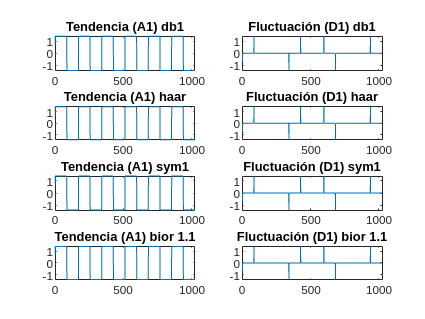

% Calculamos algunas transformadas wavelet

% Nivel 1
s = fx5;                                                % Señal
wdb1 = 'db1';                                           % Daubechies
whaar = 'haar';                                         % Haar
wsym1 = 'sym1';                                         % Symlets
wbior1_1 = 'bior1.1';                                   % Biorthogonal


% Transformadas
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                        % Daubechies
[Chaar,Lhaar] = wavedec(s,1,whaar);                     % Haar
[Csym1,Lsym1] = wavedec(s,1,wsym1);                     % Symlets
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);            % Biorthogonal


% Subseñales de tendencia y fluctiación (coeficientes)
cdb1_A1 = appcoef(Cdb1,Ldb1,wdb1,1);                    % Daubechies
cdb1_D1 = detcoef(Cdb1,Ldb1,1);                         % Daubechies

chaar_A1 = appcoef(Chaar,Lhaar,whaar,1);                % Haar
chaar_D1 = detcoef(Chaar,Lhaar,1);                      % Haar

csym1_A1 = appcoef(Csym1,Lsym1,wsym1,1);                % Symlets
csym1_D1 = detcoef(Csym1,Lsym1,1);                      % Symlets

cbior1_1_A1 = appcoef(Cbior1_1,Lbior1_1,wbior1_1,1);    % Biorthogonal
cbior1_1_D1 = detcoef(Cbior1_1,Lbior1_1,1);             % Biorthogonal


% Plots
figure; 
% Daubechies
subplot(4,2,1)
plot(cdb1_A1);title('Tendencia (A1) db1')
axis([0 length(cdb1_A1) min(cdb1_A1) max(cdb1_A1)]);
subplot(4,2,2)
plot(cdb1_D1);title('Fluctuación (D1) db1')
axis([0 length(cdb1_D1) min(cdb1_D1) max(cdb1_D1)]);

% Haar
subplot(4,2,3)
plot(chaar_A1);title('Tendencia (A1) haar')
axis([0 length(chaar_A1) min(chaar_A1) max(chaar_A1)]);
subplot(4,2,4)
plot(chaar_D1);title('Fluctuación (D1) haar')
axis([0 length(chaar_D1) min(chaar_D1) max(chaar_D1)]);

% Symlets
subplot(4,2,5)
plot(csym1_A1);title('Tendencia (A1) sym1')
axis([0 length(csym1_A1) min(csym1_A1) max(csym1_A1)]);
subplot(4,2,6)
plot(csym1_D1);title('Fluctuación (D1) sym1')
axis([0 length(csym1_D1) min(csym1_D1) max(csym1_D1)]);

% Biorthogonal
subplot(4,2,7)
plot(cbior1_1_A1);title('Tendencia (A1) bior 1.1')
axis([0 length(cbior1_1_A1) min(cbior1_1_A1) max(cbior1_1_A1)]);
subplot(4,2,8)
plot(cbior1_1_D1);title('Fluctuación (D1) bior 1.1')
axis([0 length(cbior1_1_D1) min(cbior1_1_D1) max(cbior1_1_D1)]);

- ***Calcular la energia y representar los perfiles de energia acumulada de la señal original y de la transfomada.***

**1) **$f(x)=1$

% Energia y representaci´on de perfiles de energ´ia acumulada
% de la señal original y de la transformada
%% Funci´on
s = fx1;

% Daubechies
w='db1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 2.0480e+03

[energia_C]=energy(C)         

energia_C = 2.0480e+03

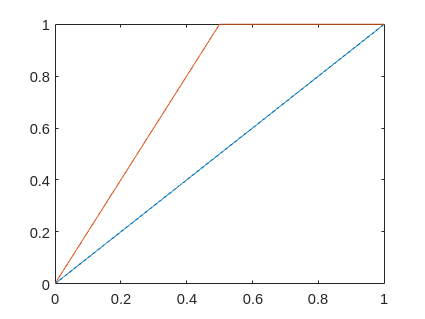

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Haar
w='Haar';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 2.0480e+03

[energia_C]=energy(C)         

energia_C = 2.0480e+03

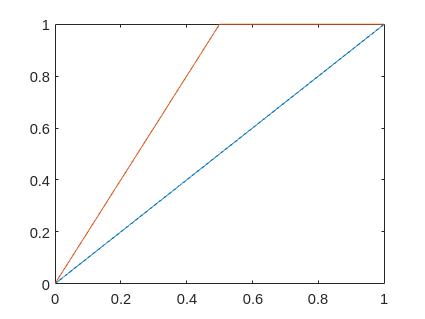

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Symlets
w='sym1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 2.0480e+03

[energia_C]=energy(C)         

energia_C = 2.0480e+03

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Biorthogonal
w='bior1.1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 2.0480e+03

[energia_C]=energy(C)         

energia_C = 2.0480e+03

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)

**2) **$f(x)=x^2(1-x)$

% Energia y representaci´on de perfiles de energ´ia acumulada
% de la señal original y de la transformada
%% Funci´on
s = fx2;

% Daubechies
w='db1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 19.4952

[energia_C]=energy(C)         

energia_C = 19.4952

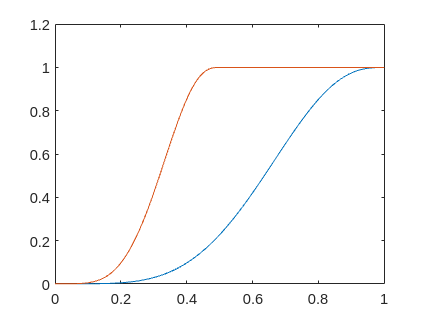

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Coiflets
w='haar';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 19.4952

[energia_C]=energy(C)         

energia_C = 19.4952

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Symlets
w='sym1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 19.4952

[energia_C]=energy(C)         

energia_C = 19.4952

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Biorthogonal
w='bior1.1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 19.4952

[energia_C]=energy(C)         

energia_C = 19.4952

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)

**3) **$f(x)=x^4(1-x)^6\cos(64\pi x)$

% Energia y representaci´on de perfiles de energ´ia acumulada
% de la señal original y de la transformada
%% Funci´on
s = fx3;

% Daubechies
w='db1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 3.8690e-04

[energia_C]=energy(C)         

energia_C = 3.8690e-04

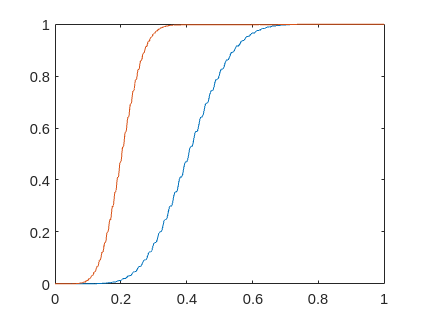

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Coiflets
w='haar';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 3.8690e-04

[energia_C]=energy(C)         

energia_C = 3.8690e-04

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Symlets
w='sym1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 3.8690e-04

[energia_C]=energy(C)         

energia_C = 3.8690e-04

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Biorthogonal
w='bior1.1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 3.8690e-04

[energia_C]=energy(C)         

energia_C = 3.8690e-04

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)

**4) **$f (x) = 1(0,2 < x < 0,3) - 3(0,4 < x < 0,5) + 2(0,5 < x < 0,8)$

% Energia y representaci´on de perfiles de energ´ia acumulada
% de la señal original y de la transformada
%% Funci´on
s = fx4;

% Daubechies
w='db1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 4506

[energia_C]=energy(C)         

energia_C = 4.5060e+03

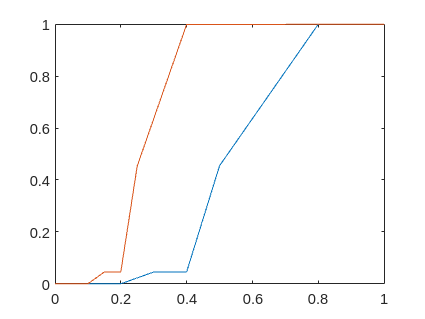

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Coiflets
w='haar';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 4506

[energia_C]=energy(C)         

energia_C = 4.5060e+03

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Symlets
w='sym1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 4506

[energia_C]=energy(C)         

energia_C = 4.5060e+03

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Biorthogonal
w='bior1.1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 4506

[energia_C]=energy(C)         

energia_C = 4.5060e+03

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)

**5) **$f (x) = sign(\sin(12\pi x))$

% Energia y representaci´on de perfiles de energ´ia acumulada
% de la señal original y de la transformada
%% Funci´on
s = fx5;

% Daubechies
w='db1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 2.0470e+03

[energia_C]=energy(C)         

energia_C = 2.0470e+03

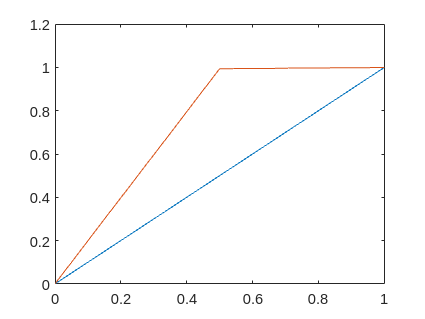

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Coiflets
w='haar';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 2.0470e+03

[energia_C]=energy(C)         

energia_C = 2.0470e+03

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Symlets
w='sym1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 2.0470e+03

[energia_C]=energy(C)         

energia_C = 2.0470e+03

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Biorthogonal
w='bior1.1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 2.0470e+03

[energia_C]=energy(C)         

energia_C = 2.0470e+03

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)

- ***En la señal cD1, contar el n´umeros de elementos nulos obtenidos***

% N´umero de valores no nulos Daubechies db1
numeroCeros_cdb1 = nnz(~cdb1_D1)

numeroCeros_cdb1 = 1017


% N´umero de valores no nulos Haar haar
numeroCeros_chaar = nnz(~chaar_D1)

numeroCeros_chaar = 1017


% N´umero de valores no nulos Symlets sym1
numeroCeros_csym1 = nnz(~csym1_D1)

numeroCeros_csym1 = 1017


% N´umero de valores no nulos Biorthogonal cbior1_1
numeroCeros_cbior1_1 = nnz(~cbior1_1_D1)

numeroCeros_cbior1_1 = 1017

- ***Hacer el an*****á*****lisis de multirresolución de la señal: a) obtener las señales de aproximación y detalle A1 y D1; b) reconstruir la señal como s=A1 + D1***

**1) **$f(x)=1$

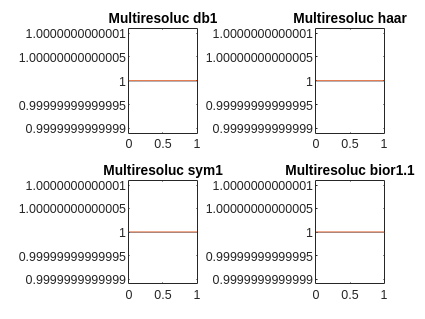

% a) Obtener las señales de aproximación y detalle A1 y D1

% Función
s = fx1;

% Daubechies
wdb1 = 'db1';
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                         
A1_db1 = wrcoef('a',Cdb1,Ldb1,wdb1,1);
D1_db1 = wrcoef('d',Cdb1,Ldb1,wdb1,1);

% Haar
whaar = 'haar';                                      
[Chaar,Lhaar] = wavedec(s,1,whaar);                                    
A1_haar = wrcoef('a',Chaar,Lhaar,whaar,1);
D1_haar = wrcoef('d',Chaar,Lhaar,whaar,1);

% Symlets
wsym1 = 'sym1';                                         
[Csym1,Lsym1] = wavedec(s,1,wsym1);                                        
A1_sym1 = wrcoef('a',Csym1,Lsym1,wsym1,1);
D1_sym1 = wrcoef('d',Csym1,Lsym1,wsym1,1);

% Biorthogonal   
wbior1_1 = 'bior1.1';
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);             
A1_bior1_1 = wrcoef('a',Cbior1_1,Lbior1_1,wbior1_1,1);
D1_bior1_1 = wrcoef('d',Cbior1_1,Lbior1_1,wbior1_1,1);



% b) Reconstruir la señal como s=A1 + D1

% Daubechies
R_db1 = A1_db1 + D1_db1;

% Haar
R_haar = A1_haar + D1_haar;

% Symlets
R_sym1 = A1_sym1 + D1_sym1;

% Biorthogonal 
R_bior1_1 = A1_bior1_1 + D1_bior1_1;


% PLOTS
figure; 
subplot(2,2,1)
plot(x,s,x,R_db1); title('Multiresoluc db1')

subplot(2,2,2)
plot(x,s,x,R_haar); title('Multiresoluc haar')

subplot(2,2,3)
plot(x,s,x,R_sym1); title('Multiresoluc sym1')

subplot(2,2,4)
plot(x,s,x,R_bior1_1); title('Multiresoluc bior1.1')

**2) **$f(x)=x^2(1-x)$

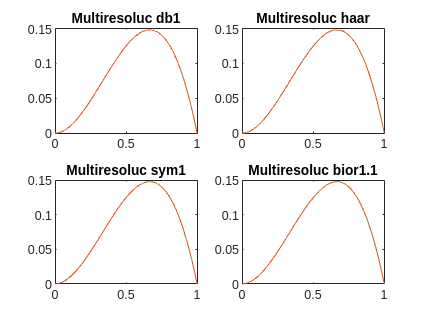

% a) Obtener las señales de aproximación y detalle A1 y D1

% Función
s = fx2;

% Daubechies
wdb1 = 'db1';
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                         
A1_db1 = wrcoef('a',Cdb1,Ldb1,wdb1,1);
D1_db1 = wrcoef('d',Cdb1,Ldb1,wdb1,1);

% Haar
whaar = 'haar';                                      
[Chaar,Lhaar] = wavedec(s,1,whaar);                                    
A1_haar = wrcoef('a',Chaar,Lhaar,whaar,1);
D1_haar = wrcoef('d',Chaar,Lhaar,whaar,1);

% Symlets
wsym1 = 'sym1';                                         
[Csym1,Lsym1] = wavedec(s,1,wsym1);                                        
A1_sym1 = wrcoef('a',Csym1,Lsym1,wsym1,1);
D1_sym1 = wrcoef('d',Csym1,Lsym1,wsym1,1);

% Biorthogonal   
wbior1_1 = 'bior1.1';
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);             
A1_bior1_1 = wrcoef('a',Cbior1_1,Lbior1_1,wbior1_1,1);
D1_bior1_1 = wrcoef('d',Cbior1_1,Lbior1_1,wbior1_1,1);



% b) Reconstruir la señal como s=A1 + D1

% Daubechies
R_db1 = A1_db1 + D1_db1;

% Haar
R_haar = A1_haar + D1_haar;

% Symlets
R_sym1 = A1_sym1 + D1_sym1;

% Biorthogonal 
R_bior1_1 = A1_bior1_1 + D1_bior1_1;


% PLOTS
figure; 
subplot(2,2,1)
plot(x,s,x,R_db1); title('Multiresoluc db1')

subplot(2,2,2)
plot(x,s,x,R_haar); title('Multiresoluc haar')

subplot(2,2,3)
plot(x,s,x,R_sym1); title('Multiresoluc sym1')

subplot(2,2,4)
plot(x,s,x,R_bior1_1); title('Multiresoluc bior1.1')

**3) **$f(x)=x^4(1-x)^6\cos(64\pi x)$

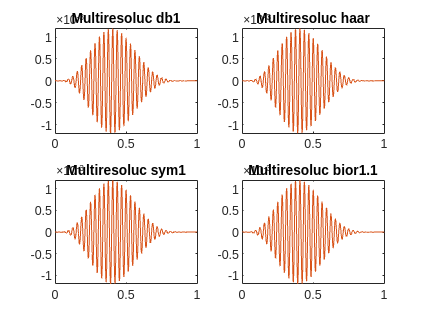

% a) Obtener las señales de aproximación y detalle A1 y D1

% Función
s = fx3;

% Daubechies
wdb1 = 'db1';
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                         
A1_db1 = wrcoef('a',Cdb1,Ldb1,wdb1,1);
D1_db1 = wrcoef('d',Cdb1,Ldb1,wdb1,1);

% Haar
whaar = 'haar';                                      
[Chaar,Lhaar] = wavedec(s,1,whaar);                                    
A1_haar = wrcoef('a',Chaar,Lhaar,whaar,1);
D1_haar = wrcoef('d',Chaar,Lhaar,whaar,1);

% Symlets
wsym1 = 'sym1';                                         
[Csym1,Lsym1] = wavedec(s,1,wsym1);                                        
A1_sym1 = wrcoef('a',Csym1,Lsym1,wsym1,1);
D1_sym1 = wrcoef('d',Csym1,Lsym1,wsym1,1);

% Biorthogonal   
wbior1_1 = 'bior1.1';
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);             
A1_bior1_1 = wrcoef('a',Cbior1_1,Lbior1_1,wbior1_1,1);
D1_bior1_1 = wrcoef('d',Cbior1_1,Lbior1_1,wbior1_1,1);



% b) Reconstruir la señal como s=A1 + D1

% Daubechies
R_db1 = A1_db1 + D1_db1;

% Haar
R_haar = A1_haar + D1_haar;

% Symlets
R_sym1 = A1_sym1 + D1_sym1;

% Biorthogonal 
R_bior1_1 = A1_bior1_1 + D1_bior1_1;


% PLOTS
figure; 
subplot(2,2,1)
plot(x,s,x,R_db1); title('Multiresoluc db1')

subplot(2,2,2)
plot(x,s,x,R_haar); title('Multiresoluc haar')

subplot(2,2,3)
plot(x,s,x,R_sym1); title('Multiresoluc sym1')

subplot(2,2,4)
plot(x,s,x,R_bior1_1); title('Multiresoluc bior1.1')

**4) **$f (x) = 1(0,2 < x < 0,3) - 3(0,4 < x < 0,5) + 2(0,5 < x < 0,8)$

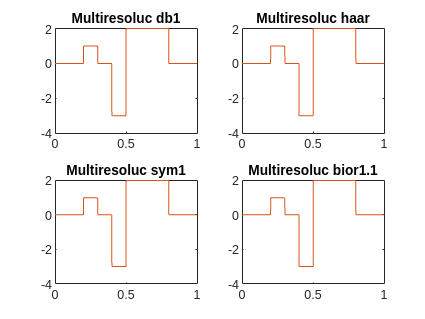

% a) Obtener las señales de aproximación y detalle A1 y D1

% Functción
s = fx4;

% Daubechies
wdb1 = 'db1';
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                         
A1_db1 = wrcoef('a',Cdb1,Ldb1,wdb1,1);
D1_db1 = wrcoef('d',Cdb1,Ldb1,wdb1,1);

% Haar
whaar = 'haar';                                      
[Chaar,Lhaar] = wavedec(s,1,whaar);                                    
A1_haar = wrcoef('a',Chaar,Lhaar,whaar,1);
D1_haar = wrcoef('d',Chaar,Lhaar,whaar,1);

% Symlets
wsym1 = 'sym1';                                         
[Csym1,Lsym1] = wavedec(s,1,wsym1);                                        
A1_sym1 = wrcoef('a',Csym1,Lsym1,wsym1,1);
D1_sym1 = wrcoef('d',Csym1,Lsym1,wsym1,1);

% Biorthogonal   
wbior1_1 = 'bior1.1';
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);             
A1_bior1_1 = wrcoef('a',Cbior1_1,Lbior1_1,wbior1_1,1);
D1_bior1_1 = wrcoef('d',Cbior1_1,Lbior1_1,wbior1_1,1);



% b) Reconstruir la señal como s=A1 + D1

% Daubechies
R_db1 = A1_db1 + D1_db1;

% Haar
R_haar = A1_haar + D1_haar;

% Symlets
R_sym1 = A1_sym1 + D1_sym1;

% Biorthogonal 
R_bior1_1 = A1_bior1_1 + D1_bior1_1;


% PLOTS
figure; 
subplot(2,2,1)
plot(x,s,x,R_db1); title('Multiresoluc db1')

subplot(2,2,2)
plot(x,s,x,R_haar); title('Multiresoluc haar')

subplot(2,2,3)
plot(x,s,x,R_sym1); title('Multiresoluc sym1')

subplot(2,2,4)
plot(x,s,x,R_bior1_1); title('Multiresoluc bior1.1')

**5) **$f (x) = sign(\sin(12\pi x))$

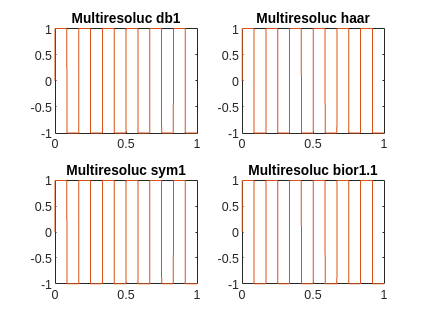

% a) Obtener las señales de aproximación y detalle A1 y D1

% Functción
s = fx5;

% Daubechies
wdb1 = 'db1';
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                         
A1_db1 = wrcoef('a',Cdb1,Ldb1,wdb1,1);
D1_db1 = wrcoef('d',Cdb1,Ldb1,wdb1,1);

% Haar
whaar = 'haar';                                      
[Chaar,Lhaar] = wavedec(s,1,whaar);                                    
A1_haar = wrcoef('a',Chaar,Lhaar,whaar,1);
D1_haar = wrcoef('d',Chaar,Lhaar,whaar,1);

% Symlets
wsym1 = 'sym1';                                         
[Csym1,Lsym1] = wavedec(s,1,wsym1);                                        
A1_sym1 = wrcoef('a',Csym1,Lsym1,wsym1,1);
D1_sym1 = wrcoef('d',Csym1,Lsym1,wsym1,1);

% Biorthogonal   
wbior1_1 = 'bior1.1';
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);             
A1_bior1_1 = wrcoef('a',Cbior1_1,Lbior1_1,wbior1_1,1);
D1_bior1_1 = wrcoef('d',Cbior1_1,Lbior1_1,wbior1_1,1);



% b) Reconstruir la señal como s=A1 + D1

% Daubechies
R_db1 = A1_db1 + D1_db1;

% Haar
R_haar = A1_haar + D1_haar;

% Symlets
R_sym1 = A1_sym1 + D1_sym1;

% Biorthogonal 
R_bior1_1 = A1_bior1_1 + D1_bior1_1;


% PLOTS
figure; 
subplot(2,2,1)
plot(x,s,x,R_db1); title('Multiresoluc db1')

subplot(2,2,2)
plot(x,s,x,R_haar); title('Multiresoluc haar')

subplot(2,2,3)
plot(x,s,x,R_sym1); title('Multiresoluc sym1')

subplot(2,2,4)
plot(x,s,x,R_bior1_1); title('Multiresoluc bior1.1')

- ***Reconstruir la señal original con la transformada wavelet inversa. Comparar gráficamente las dos formas de reconstrucción.***

**1) **$f(x)=1$

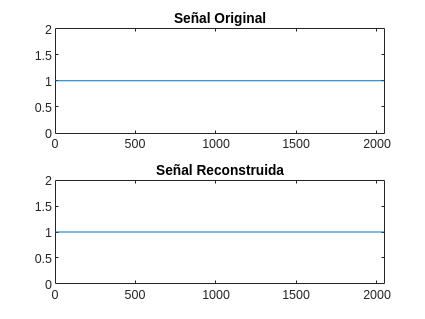

% Función
s = fx1;

% Daubechies
w = 'db1';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);


% Haar
w = 'haar';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);


% Symlets
w = 'sym1';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);


% Biorthogonal
w = 'bior1.1';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);

**2) **$f(x)=x^2(1-x)$

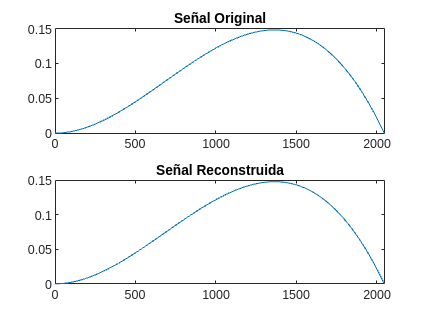

% Función
s = fx2;

% Daubechies
w = 'db1';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);


% Haar
w = 'haar';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);


% Symlets
w = 'sym1';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);


% Biorthogonal
w = 'bior1.1';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);

**3) **$f(x)=x^4(1-x)^6\cos(64\pi x)$

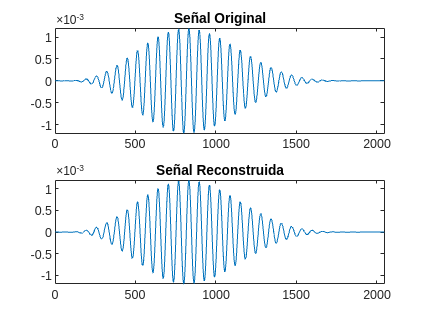

% Función
s = fx3;

% Daubechies
w = 'db1';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);


% Haar
w = 'haar';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);


% Symlets
w = 'sym1';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);


% Biorthogonal
w = 'bior1.1';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);

**4) **$f (x) = 1(0,2 < x < 0,3) - 3(0,4 < x < 0,5) + 2(0,5 < x < 0,8)$

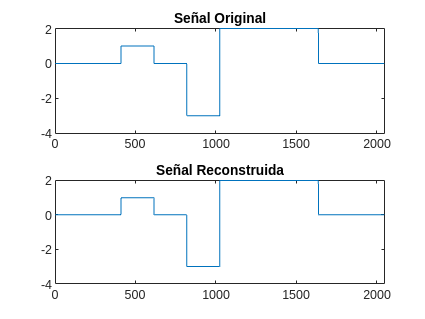

% Función
s = fx4;

% Daubechies
w = 'db1';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);


% Haar
w = 'haar';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);


% Symlets
w = 'sym1';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);


% Biorthogonal
w = 'bior1.1';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);

**5) **$f (x) = sign(\sin(12\pi x))$

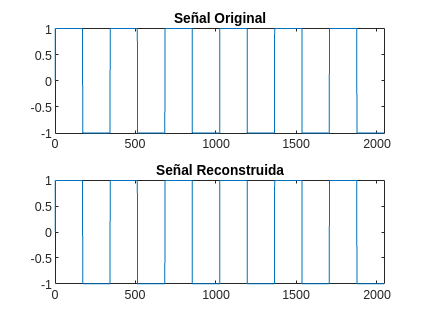

% Función
s = fx5;

% Daubechies
w = 'db1';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);


% Haar
w = 'haar';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);


% Symlets
w = 'sym1';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);


% Biorthogonal
w = 'bior1.1';
[C,L] = wavedec(s,1,w);
recSignal = waverec(C,L,w); % Reconstrucción 
figure;
subplot(2, 1, 1);
plot(s);
title('Señal Original');
xlim([0 2048]);
subplot(2, 1, 2);
plot(recSignal);
title('Señal Reconstruida');
xlim([0 2048]);

## Ejercicio 3. Análisis de orden superior

**Para cada una de las señales anteriores realizar las siguentes tareas:**

- **Calcular las transformadas wavelet de niveles 2, 3 y 4. Extraer las correspondientes subseñales de tendencia y fluctuaci´on y representar.**

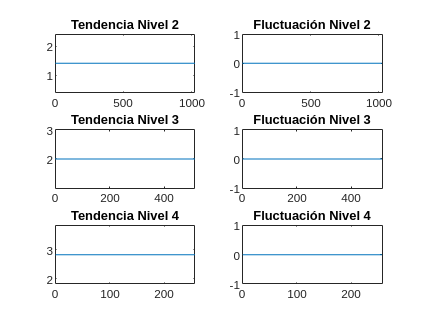

% f(x) = 1
s = ones(size(x));
waveletTransform(s)

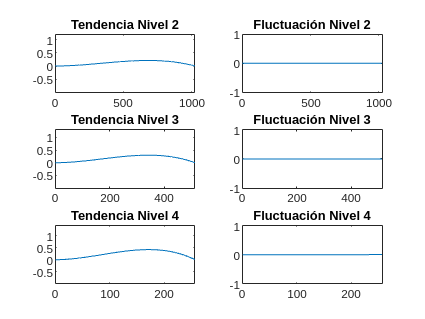


% f(x) = x^2(1 − x)
s = x.^2.*(1-x);
waveletTransform(s)

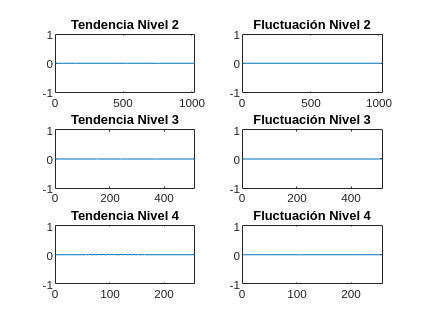


% f(x) = x^4 (1 − x)^6 cos(64πx)
s = x.^4.*(1-x).^6.*cos(64*pi*x);
waveletTransform(s)

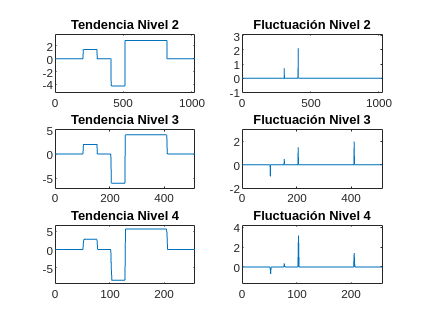


% f(x) = 1(0,2 < x < 0,3) − 3(0,4 < x < 0,5) + 2(0,5 < x < 0,8)
s = zeros(size(x));
s((0.2 < x) & (x < 0.3)) = 1;
s((0.4 < x) & (x < 0.5)) = -3;
s((0.5 < x) & (x < 0.8)) = 2;
waveletTransform(s)

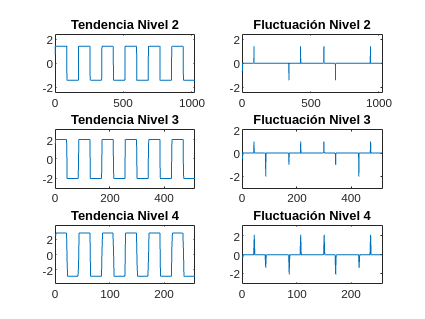


% f(x) = sign(sin(12πx))
s = sign(sin(12*pi*x));
waveletTransform(s)

- **Calcular la energ´ıa y representar los perfiles de energ´ıa acumulada de la señal original y de la transfomada. Comprobar que la transformaci´on preserva la energ´ıa.**

La transformación preserva la energía


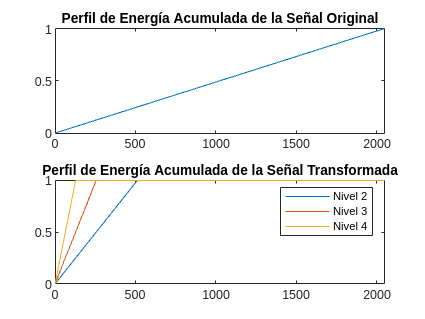

% f(x) = 1
s = ones(size(x));
energia_acum_pres(s)

La transformación preserva la energía


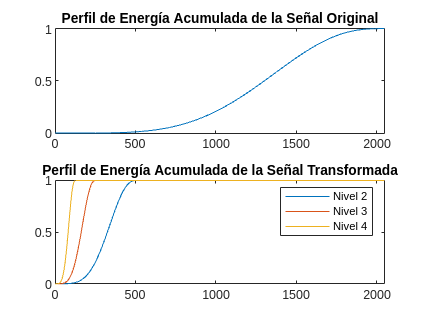


% f(x) = x^2(1 − x)
s = x.^2.*(1-x);
energia_acum_pres(s)

La transformación preserva la energía


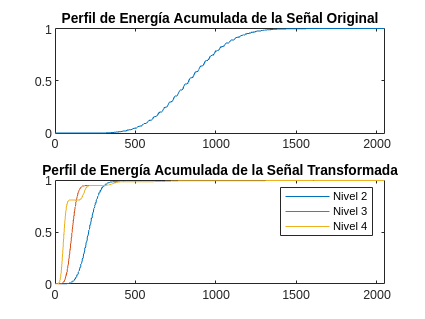


% f(x) = x^4 (1 − x)^6 cos(64πx)
s = x.^4.*(1-x).^6.*cos(64*pi*x);
energia_acum_pres(s)

La transformación preserva la energía


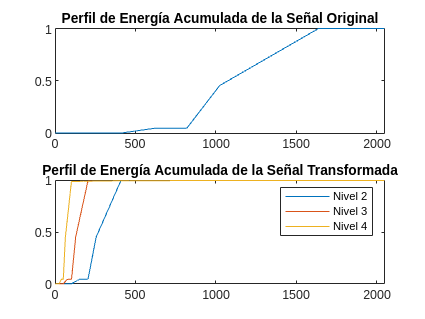


% f(x) = 1(0,2 < x < 0,3) − 3(0,4 < x < 0,5) + 2(0,5 < x < 0,8)
s = zeros(size(x));
s((0.2 < x) & (x < 0.3)) = 1;
s((0.4 < x) & (x < 0.5)) = -3;
s((0.5 < x) & (x < 0.8)) = 2;
energia_acum_pres(s)

La transformación preserva la energía


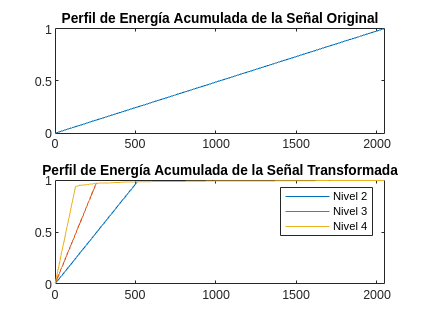


% f(x) = sign(sin(12πx))
s = sign(sin(12*pi*x));
energia_acum_pres(s)

- **Analizar el n´umero de ceros correspondiente a la señal de fluctuaci´on de cada nivel: cD1,cD2,cD3,...**

% f(x) = 1
s = ones(size(x));
ceros(s)

Número de ceros en D2: 1024
Número de ceros en D3: 1024
Número de ceros en D4: 1024



% f(x) = x^2(1 − x)
s = x.^2.*(1-x);
ceros(s)

Número de ceros en D2: 0
Número de ceros en D3: 0
Número de ceros en D4: 0



% f(x) = x^4 (1 − x)^6 cos(64πx)
s = x.^4.*(1-x).^6.*cos(64*pi*x);
ceros(s)

Número de ceros en D2: 0
Número de ceros en D3: 0
Número de ceros en D4: 0



% f(x) = 1(0,2 < x < 0,3) − 3(0,4 < x < 0,5) + 2(0,5 < x < 0,8)
s = zeros(size(x));
s((0.2 < x) & (x < 0.3)) = 1;
s((0.4 < x) & (x < 0.5)) = -3;
s((0.5 < x) & (x < 0.8)) = 2;
ceros(s)

Número de ceros en D2: 920
Número de ceros en D3: 920
Número de ceros en D4: 920



% f(x) = sign(sin(12πx))
s = sign(sin(12*pi*x));
ceros(s)

Número de ceros en D2: 1017
Número de ceros en D3: 1017
Número de ceros en D4: 1017


- **Hacer el an´alisis de multirresoluci´on de la señal: a) obtener las señales de aproximaci´on y detalles al nivel correspondiente AN y DN, D(N-1),..., D2,D1; b) reconstruir la señal como s=AN+DN+...+D1.**

A1: 1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      1.4142      

Arrays have incompatible sizes for this operation.

Error in ChristianParedesAguilera.Practica1>multirresol (line 1429)
        s_reconstruida = s_reconstruida + A + sum(cell2mat(D));

Related documentation

- **Reconstruir la señal original con la transformada wavelet inversa. Comparar gr´aficamente las dos formas de reconstrucci´on.**

%

## ***FUNCIONES***

function [y] = energy(x)
%ENERGY Computes the energy of a signal.
%  y = ENERGY(x) returns the energy of x.
%  The energy computed as the sum of the 
%  square of the elements of x.

%   See also CUMENERGY.

y = norm(x)^2;
end
function [y] = cumenergy(x)
%CUMENERGY Computes the normalized cumulative energy profile.
%  y = CUMENERGY(x) creates a vector y with the normalized
%  cumulative energy profile of vector x.

%   See also ENERGY.

y = cumsum(x.^2)/(norm(x)^2);
end


function waveletTransform(s)

    x = linspace(0,1,2048);
    % Definir la función wavelet
    w = 'haar';

    % Calcular las transformadas wavelet de niveles 2, 3 y 4
    [C2,L2] = wavedec(s,2,w);
    [C3,L3] = wavedec(s,3,w);
    [C4,L4] = wavedec(s,4,w);

    % Extraer las subseñales de tendencia y fluctuación
    [A2,D2] = dwt(s,w);
    [A3,D3] = dwt(A2,w);
    [A4,D4] = dwt(A3,w);

    % Crear una figura para la comparación gráfica
    figure;

    % Dibujar las subseñales de tendencia
    subplot(3, 2, 1);
    plot(A2);
    title('Tendencia Nivel 2');
    axis([0 length(A2) min(A2)-1 max(A2)+1]); % Ajustar los ejes

    subplot(3, 2, 3);
    plot(A3);
    title('Tendencia Nivel 3');
    axis([0 length(A3) min(A3)-1 max(A3)+1]); % Ajustar los ejes

    subplot(3, 2, 5);
    plot(A4);
    title('Tendencia Nivel 4');
    axis([0 length(A4) min(A4)-1 max(A4)+1]); % Ajustar los ejes

    % Dibujar las subseñales de fluctuación
    subplot(3, 2, 2);
    plot(D2);
    title('Fluctuación Nivel 2');
    axis([0 length(D2) min(D2)-1 max(D2)+1]); % Ajustar los ejes

    subplot(3, 2, 4);
    plot(D3);
    title('Fluctuación Nivel 3');
    axis([0 length(D3) min(D3)-1 max(D3)+1]); % Ajustar los ejes

    subplot(3, 2, 6);
    plot(D4);
    title('Fluctuación Nivel 4');
    axis([0 length(D4) min(D4)-1 max(D4)+1]); % Ajustar los ejes
end


function energia_acum_pres(s)
    % Definir la función wavelet
    w = 'haar';

    % Calcular las transformadas wavelet de niveles 2, 3 y 4
    [C2,L2] = wavedec(s,2,w);
    [C3,L3] = wavedec(s,3,w);
    [C4,L4] = wavedec(s,4,w);

    % Extraer las subseñales de tendencia y fluctuación
    [A2,D2] = dwt(s,w);
    [A3,D3] = dwt(A2,w);
    [A4,D4] = dwt(A3,w);

    % Calcular la energía de la señal original y de la señal transformada
    energy_s = energy(s);
    energy_C2 = energy(C2);
    energy_C3 = energy(C3);
    energy_C4 = energy(C4);

    % Calcular los perfiles de energía acumulada
    cumenergy_s = cumenergy(s);
    cumenergy_C2 = cumenergy(C2);
    cumenergy_C3 = cumenergy(C3);
    cumenergy_C4 = cumenergy(C4);

    % Comprobar que la transformación preserva la energía
    if abs(energy_s - energy_C2) < 1e-6 && abs(energy_s - energy_C3) < 1e-6 && abs(energy_s - energy_C4) < 1e-6
        disp('La transformación preserva la energía');
    else
        disp('La transformación no preserva la energía');
    end

    % Crear una figura para la comparación gráfica
    figure;

    % Dibujar los perfiles de energía acumulada
    subplot(2, 1, 1);
    plot(cumenergy_s);
    title('Perfil de Energía Acumulada de la Señal Original');
    axis([0 length(s) 0 1]); % Ajustar los ejes

    subplot(2, 1, 2);
    plot(cumenergy_C2);
    hold on;
    plot(cumenergy_C3);
    plot(cumenergy_C4);
    title('Perfil de Energía Acumulada de la Señal Transformada');
    axis([0 length(s) 0 1]); % Ajustar los ejes
    legend('Nivel 2', 'Nivel 3', 'Nivel 4');
end


function ceros(s)
    % Definir la función wavelet
    w = 'haar';

    % Calcular las transformadas wavelet de niveles 2, 3 y 4
    [C2,L2] = wavedec(s,2,w);
    [C3,L3] = wavedec(s,3,w);
    [C4,L4] = wavedec(s,4,w);

    % Extraer las subseñales de fluctuación
    D2 = detcoef(C2,L2,1);
    D3 = detcoef(C3,L3,1);
    D4 = detcoef(C4,L4,1);

    % Calcular el número de ceros en las señales de fluctuación
    numZeros_D2 = nnz(~D2);
    numZeros_D3 = nnz(~D3);
    numZeros_D4 = nnz(~D4);

    % Mostrar el número de ceros
    disp(['Número de ceros en D2: ', num2str(numZeros_D2)]);
    disp(['Número de ceros en D3: ', num2str(numZeros_D3)]);
    disp(['Número de ceros en D4: ', num2str(numZeros_D4)]);
end